%select teh top 200 columns and run the analysis on them

% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now

remlstatsubj={7349,7361,  7375,7383,  7402,  7403,  7404};
subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
for subj=allsubj%remlstatsubj%allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls.mat']; %this is the S1 sampled matrices
    if exist(columnartsfile,"file")
%         disp(subj)
        disp([num2str(subj{:}) ' subject columnar info r'])
        plotidx=plotidx+1;
        [stat,columndistribution,layerwisestat]=BK_layer_sampling_pain_study_pipeline(subj,'glmestimate');
        allsubjlayer{plotidx}=layerwisestat;
        allsubjcoldistr{plotidx}=columndistribution;
        allsubjstat{plotidx}=stat;
%         subplot(subplotsize(1), subplotsize(2), plotidx);
%         hcogn=histogram(stat.T(:,:,1),'BinLimits',[-5,5],'FaceColor', 'blue');
%         hold on
%         hpain=histogram(stat.T(:,:,2),'BinLimits',[-5,5],'FaceColor', 'red');
%         hconj=histogram(stat.T(:,:,3),'BinLimits',[-5,5],'FaceColor', 'green');
%         xline(1,'-','LineWidth', 1.5,'Color', 'blue');
%         xline(0,'-','LineWidth', 1.5,'Color', 'red');
%         title(num2str(subj{:}))
%         if plotidx==1
%             legend('Cognitive act (Blue)', 'Pain act (Red)','Conjuction act (Blue)','t>1', 'Location', 'northwestoutside');
%         end
%         
%         hold off
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7349 subject has  no sampled cluster
7356 subject has  no sampled cluster


7361 subject columnar info r


Time for one subject to process:Elapsed time is 34.411072 seconds.


7375 subject columnar info r


Time for one subject to process:Elapsed time is 3.881800 seconds.


7376 subject columnar info r


Time for one subject to process:Elapsed time is 3.352389 seconds.


7383 subject columnar info r


Time for one subject to process:Elapsed time is 3.383457 seconds.


7402 subject columnar info r


Time for one subject to process:Elapsed time is 5.213620 seconds.


7403 subject columnar info r


Time for one subject to process:Elapsed time is 3.559050 seconds.


7404 subject columnar info r


Time for one subject to process:Elapsed time is 2.947434 seconds.


7405 subject columnar info r


Time for one subject to process:Elapsed time is 2.745025 seconds.


7408 subject columnar info r


Time for one subject to process:Elapsed time is 4.001914 seconds.


7414 subject columnar info r


Time for one subject to process:Elapsed time is 3.164852 seconds.


7415 subject columnar info r


Time for one subject to process:Elapsed time is 3.502477 seconds.


7425 subject columnar info r


Time for one subject to process:Elapsed time is 3.335751 seconds.


7426 subject columnar info r


Time for one subject to process:Elapsed time is 3.567504 seconds.


7433 subject columnar info r


Time for one subject to process:Elapsed time is 3.148554 seconds.


7434 subject columnar info r


Time for one subject to process:Elapsed time is 3.149287 seconds.


7435 subject columnar info r


Time for one subject to process:Elapsed time is 3.119121 seconds.


7443 subject columnar info r


Time for one subject to process:Elapsed time is 3.067395 seconds.


7444 subject columnar info r


Time for one subject to process:Elapsed time is 4.081832 seconds.


7445 subject columnar info r


Time for one subject to process:Elapsed time is 3.262066 seconds.


7448 subject columnar info r


Time for one subject to process:Elapsed time is 2.945006 seconds.


7449 subject columnar info r


Time for one subject to process:Elapsed time is 3.070779 seconds.


7452 subject columnar info r


Time for one subject to process:Elapsed time is 3.286796 seconds.


7453 subject columnar info r


Time for one subject to process:Elapsed time is 3.658294 seconds.


7454 subject columnar info r


Time for one subject to process:Elapsed time is 3.449614 seconds.


7455 subject columnar info r


Time for one subject to process:Elapsed time is 3.169786 seconds.


7456 subject columnar info r


Time for one subject to process:Elapsed time is 3.159355 seconds.


7457 subject columnar info r


Time for one subject to process:Elapsed time is 3.151352 seconds.


7468 subject columnar info r


Time for one subject to process:Elapsed time is 2.916872 seconds.


7469 subject columnar info r


Time for one subject to process:Elapsed time is 3.038486 seconds.


7482 subject columnar info r


Time for one subject to process:Elapsed time is 3.103051 seconds.


7484 subject columnar info r


Time for one subject to process:Elapsed time is 3.118347 seconds.


7485 subject columnar info r


Time for one subject to process:Elapsed time is 2.837174 seconds.



%when all the conditions are esimated separately, we can visualize the
%indiviudal ßs as a function of layer
%visualize hte ß distribution as a function of layers
%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);

    HCHP(subj,:)=allsubjlayer{subj}.beta(:,:,1);
    HCLP(subj,:)=allsubjlayer{subj}.beta(:,:,2);

    LCHP(subj,:)=allsubjlayer{subj}.beta(:,:,3);
    LCLP(subj,:)=allsubjlayer{subj}.beta(:,:,4);

    effofcognlcminusHc_ofhighpain_cognsuppression(subj,:)=allsubjlayer{subj}.beta(:,:,3)-allsubjlayer{subj}.beta(:,:,1);


%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end

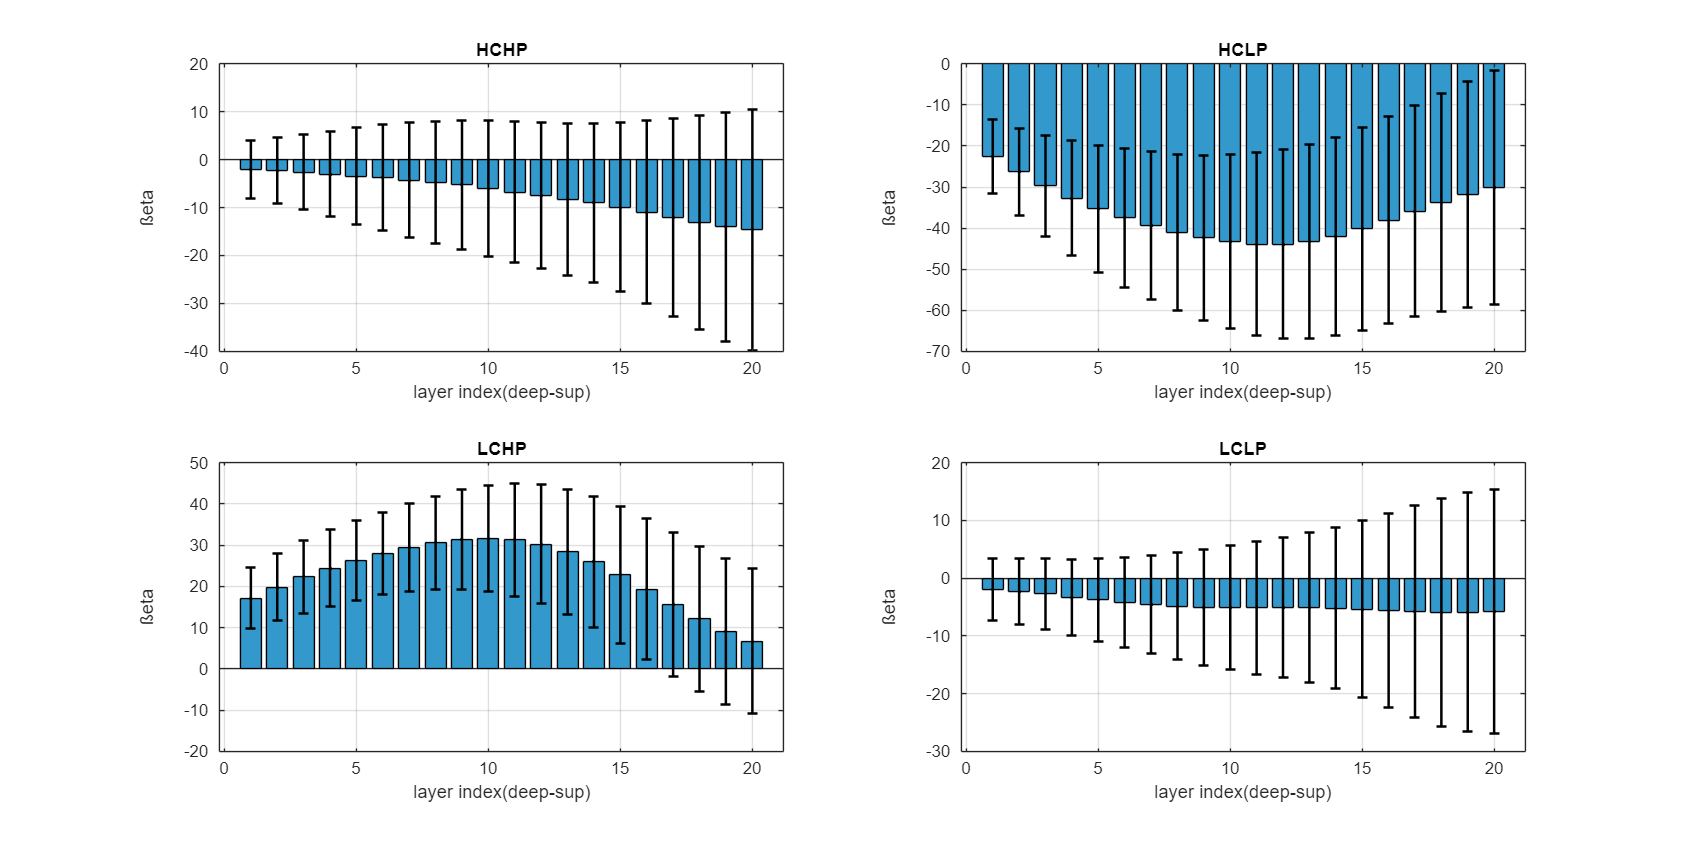

figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
alldata={HCHP, HCLP,LCHP,LCLP};
alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
for dataidx=1:4
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
%     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
    plotidx=plotidx+1;
    data=alldata{dataidx};
% Example matrix of size 10x20
%     data = allsubjlayerresp; % Random data for demonstration
    
    % Calculate column-wise mean and standard deviation
    columnMeans = mean(data, 1); % Mean of each column
    columnStdDevs = std(data, 0, 1); % Standard deviation of each column
    
    % Create the bar plot
    subplot(2,2,plotidx)
    bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
    hold on;
    
    % Add error bars
    errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
        'k.', 'LineWidth', 1.5); % Error bars in black
    
    % Customize the plot
    xlabel('layer index(deep-sup)');
    ylabel('ßeta');
    title(alldatanm{dataidx});
    grid on;
    hold off;
end

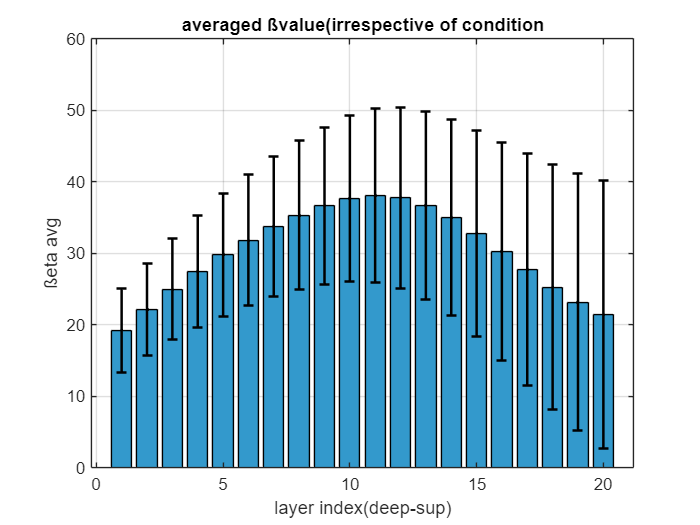

alldata=[HCHP; HCLP;LCHP;LCLP];
columnMeans = mean(data, 1); % Mean of each column
columnStdDevs = std(data, 0, 1); % Standard deviation of each column

% Create the bar plot
% subplot(2,2,plotidx)
bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
hold on;

% Add error bars
errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
    'k.', 'LineWidth', 1.5); % Error bars in black

% Customize the plot
xlabel('layer index(deep-sup)');
ylabel('ßeta avg');
title('averaged ßvalue(irrespective of condition');

grid on;

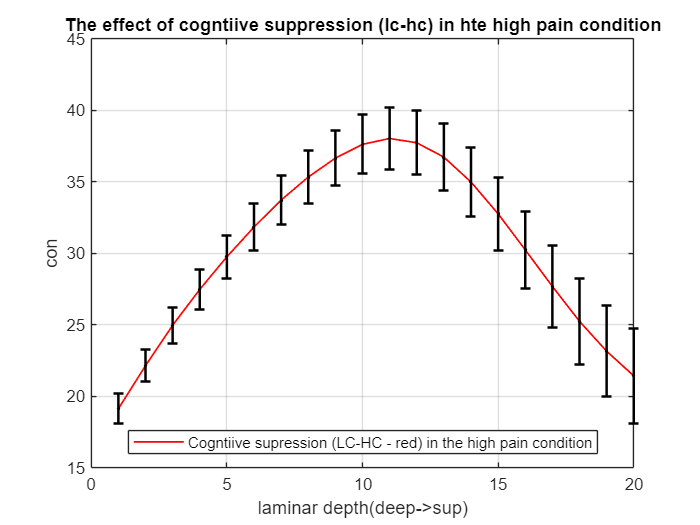

% Example matrix of size 10x20
data = effofcognlcminusHc_ofhighpain_cognsuppression; % Random data for demonstration

% Calculate column-wise mean and standard deviation
columnMeans = mean(data, 1); % Mean of each column
% columnStdDevs = std(data, 0, 1); % Standard deviation of each column
columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error

% Create the bar plot
figure;
lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
% bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
hold on;

% Add error bars
errorbar(1:length(columnMeans), columnMeans, columnStdErrors, ...
    'k.', 'LineWidth', 1.5); % Error bars in black

% Customize the plot
xlabel('laminar depth(deep->sup)');
ylabel('con');
title('The effect of cogntiive suppression (lc-hc) in hte high pain condition');
grid on;
legend([lineHandle1], ...
        {'Cogntiive supression (LC-HC - red) in the high pain condition'}, ...
        'Location', 'south');
hold off;

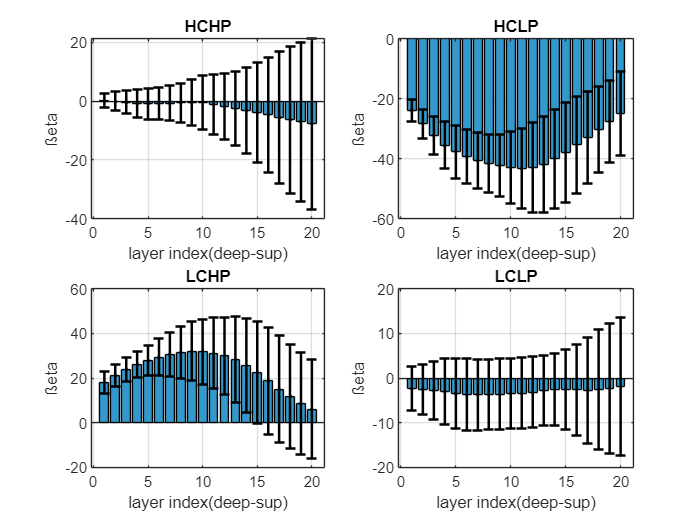

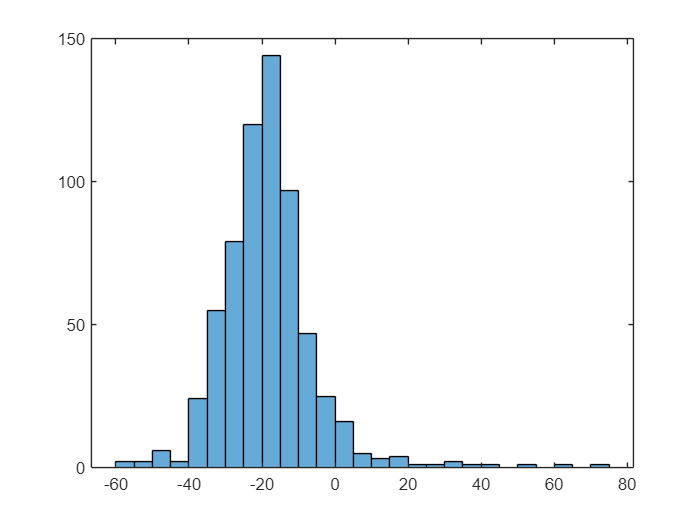

%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
    HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
    LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);


%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
% 
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end

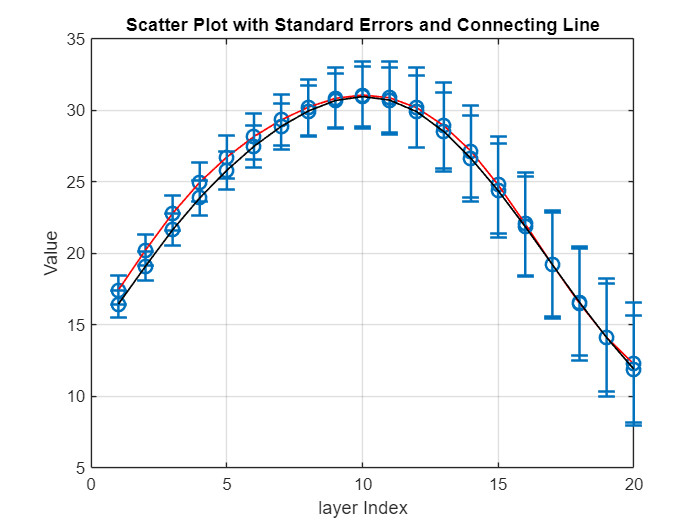

% this is the higpain-lowpain contrast for the high and low cognition
% data = HC_onpain; % Random data for demonstration
figure;
alldata={HC_onpain, LC_onpain};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer Index');
    ylabel('Value');
    title('Scatter Plot with Standard Errors and Connecting Line');
    grid on;
end
hold off;

% this is the effect of pain(bottom up) and effect of cogntition (top-down) in the layer profile

for subj=1:length(allsubjlayer)
    topdown_beta(subj,:)=allsubjlayer{subj}.beta(:,1,1);
    bottomup_beta(subj,:)=allsubjlayer{subj}.beta(:,1,2);
    

    
    topdown_t(subj,:)=allsubjlayer{subj}.T(:,1,1);
    bottomup_t(subj,:)=allsubjlayer{subj}.T(:,1,2);

%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
% 
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end

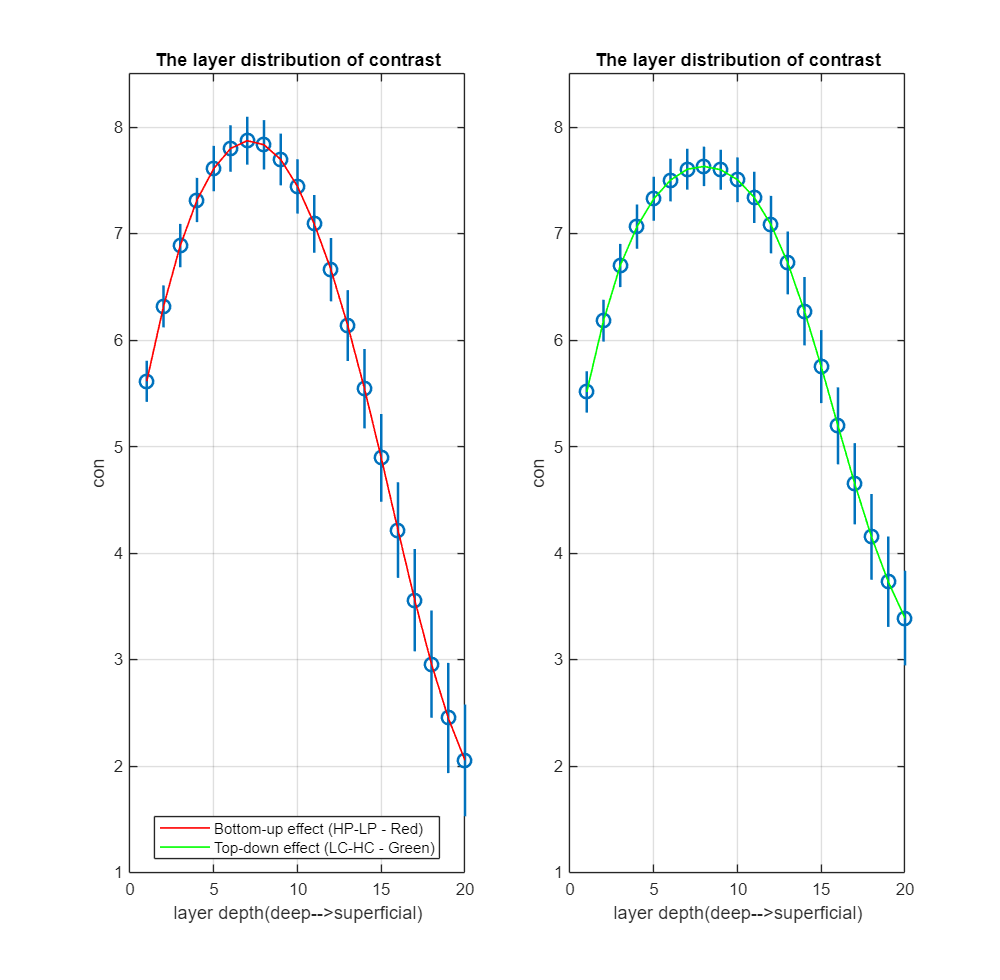


figure('Position',[100, 100, 2400, 1200]);
alldata_beta={bottomup_beta, topdown_beta};
% alldata_t={bottomup_t,topdown_t};
% for stattype=1:2
    for dataidx=1:2
        % Calculate column-wise mean and standard error
        if stattype==1
            data=alldata_beta{dataidx};
            titlenm='The layer distribution of contrast values';
            ylabltxt='beta';
        elseif stattype==2
            data=alldata_t{dataidx};
            titlenm='The layer distribution of t stat';
            ylabltxt='t-stat';
        end
        titlenm='The layer distribution of contrast';
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
%         subplot(1,2,stattype)
        subplot(1,2,dataidx)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        ylim([1 8.5])
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;

% end

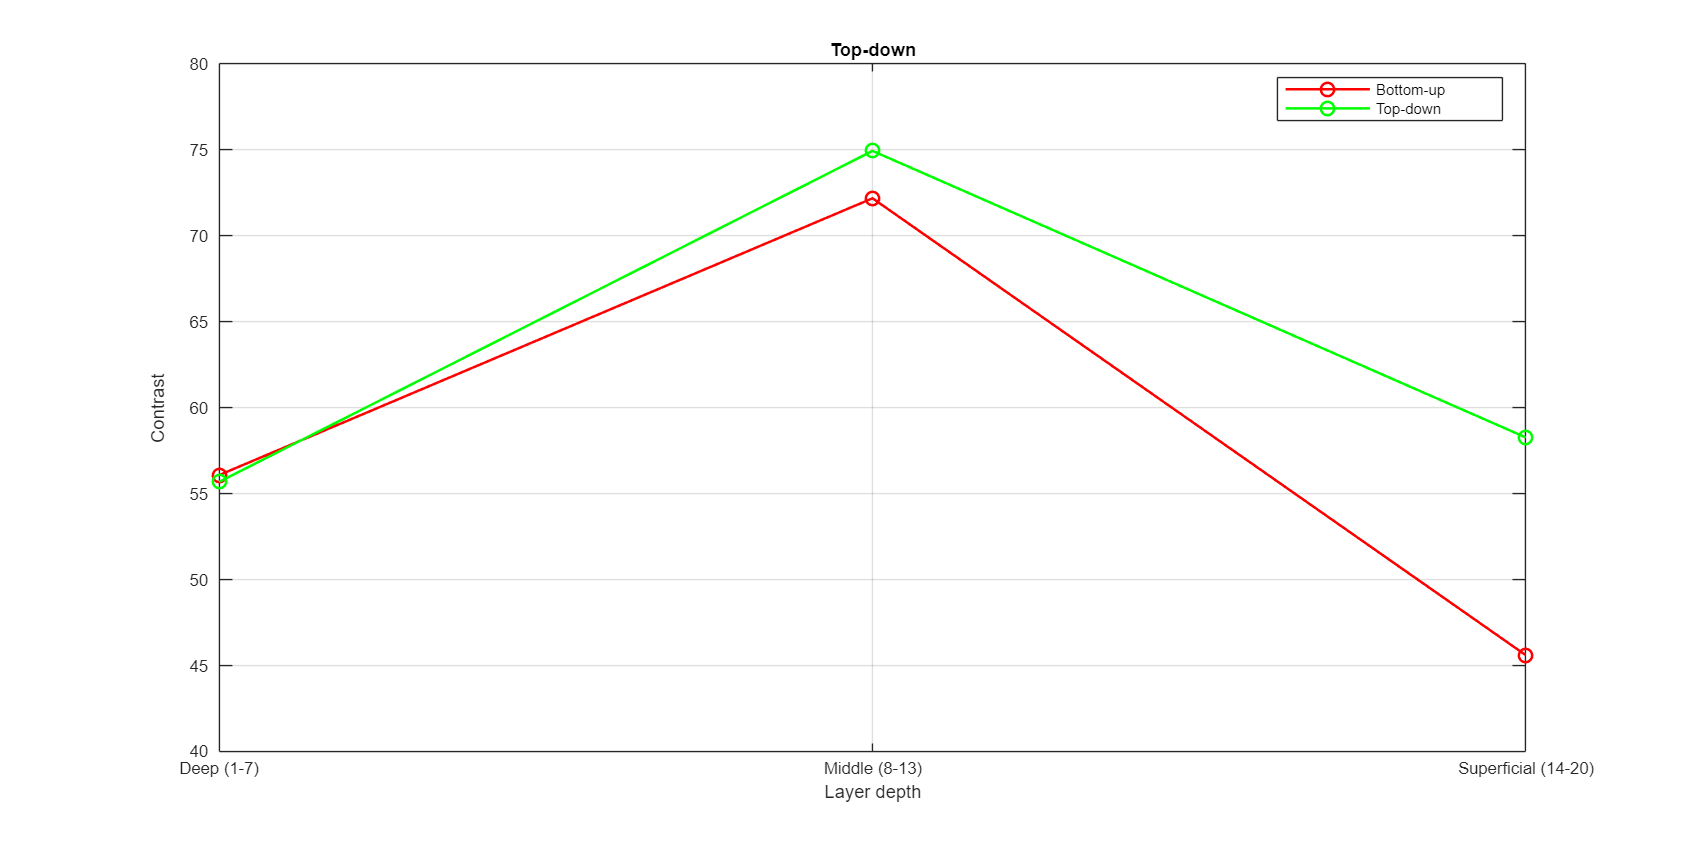

% Create a separate figure
figure('Position', [100, 100, 2400, 1200]);

% Define bin ranges
binRanges = {[1:7], [8:13], [14:20]};
binLabels = {'Deep (1-7)', 'Middle (8-13)', 'Superficial (14-20)'};

% Initialize data for binned means
binnedMeans = zeros(2, length(binRanges)); % Two rows for bottom-up and top-down
ploidx=0;
for dataidx = 1:2
    ploidx=ploidx+1;
    if dataidx == 1
        data = alldata_beta{dataidx};
        legendLabel = 'Bottom-up';
        lineColor = 'r';
    else
        data = alldata_beta{dataidx};
        legendLabel = 'Top-down';
        lineColor = 'g';
    end
%     subplot(1,2,ploidx)
    % Compute the means for each bin
    for binIdx = 1:length(binRanges)
        binCols = binRanges{binIdx}; % Get the column indices for the bin
        binnedMeans(dataidx, binIdx) = mean(mean(data(:, binCols), 1)); % Mean over bin
    end
    
    % Plot the binned means
    plot(1:length(binRanges), binnedMeans(dataidx, :), '-o', 'LineWidth', 1.5, ...
        'MarkerSize', 8, 'Color', lineColor, 'DisplayName', legendLabel);
    hold on
    
    xticks(1:length(binRanges));
    xticklabels(binLabels);
    xlabel('Layer depth');
    ylabel('Contrast');
    
    grid on;
    title(legendLabel);
    legend('Location', 'northeast');
    ylim([40 80])
end

% Customize the plot


hold off;

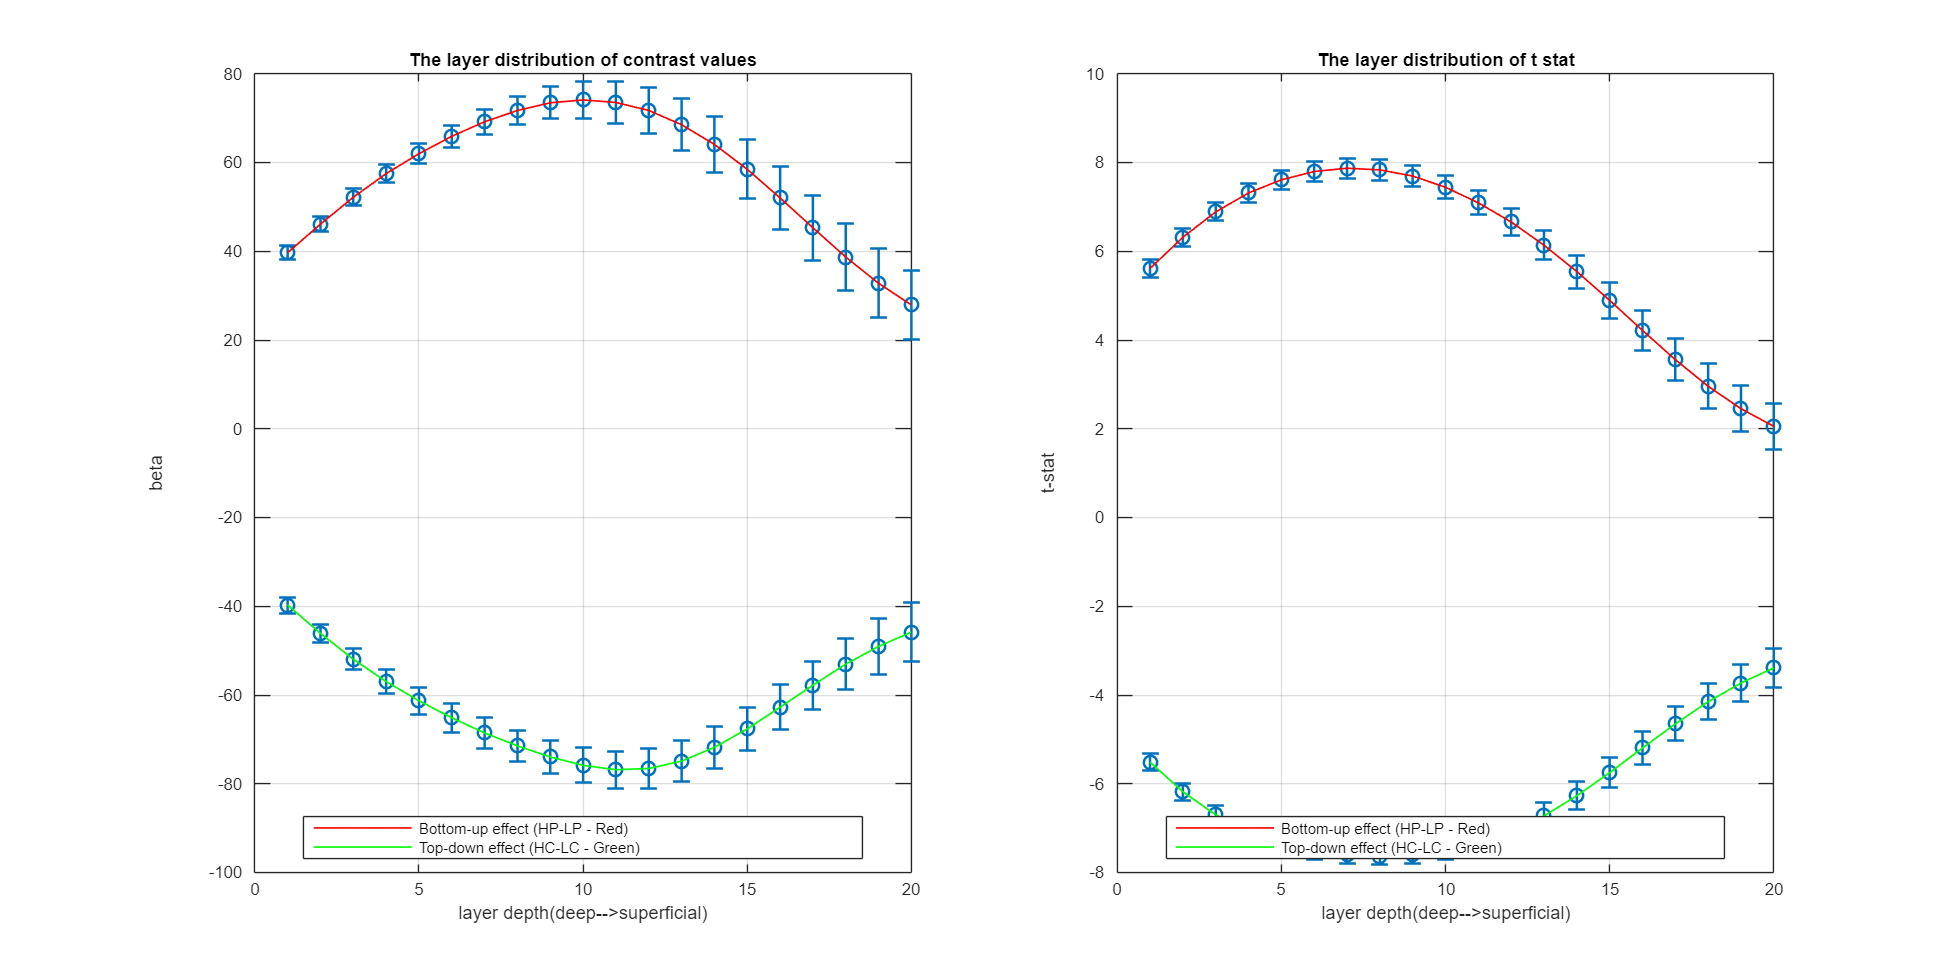



for subj=1:length(allsubjlayer)
    
    topdown_beta(subj,:)=allsubjlayer{subj}.beta(:,1,1);
    bottomup_beta(subj,:)=allsubjlayer{subj}.beta(:,1,2);
    
    topdown_t(subj,:)=allsubjlayer{subj}.T(:,1,1);
    bottomup_t(subj,:)=allsubjlayer{subj}.T(:,1,2);

%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
% 
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end
figure('Position',[100, 100, 2400, 1200]);
alldata_beta={bottomup_beta, topdown_beta};
alldata_t={bottomup_t,topdown_t};
for stattype=1:2
    for dataidx=1:2
        % Calculate column-wise mean and standard error
        if stattype==1
            data=alldata_beta{dataidx};
            titlenm='The layer distribution of contrast values';
            ylabltxt='beta';
        elseif stattype==2
            data=alldata_t{dataidx};
            titlenm='The layer distribution of t stat';
            ylabltxt='t-stat';
        end
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,stattype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (HC-LC - Green)'}, ...
        'Location', 'south');
    hold off;
end